### *Page 217, Problem 3.31*

*Creating a Random Variable "X" and Stem Plotiing its PMF*

X = linspace(1,6,6)

X =      1     2     3     4     5     6


Y = [1/6 1/6 1/6 1/6 1/6 1/6]

Y =     0.1667    0.1667    0.1667    0.1667    0.1667    0.1667


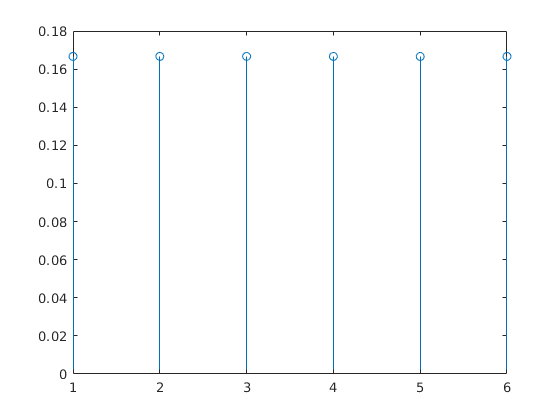

stem(X,Y)

Now we will plotting the curve of a new random variable T = (1/N)*(summations of X_i)

We know that PDF of Suumation of 2 Random Variables is their Convolution of PDFs. Applying the same principle in this situation.

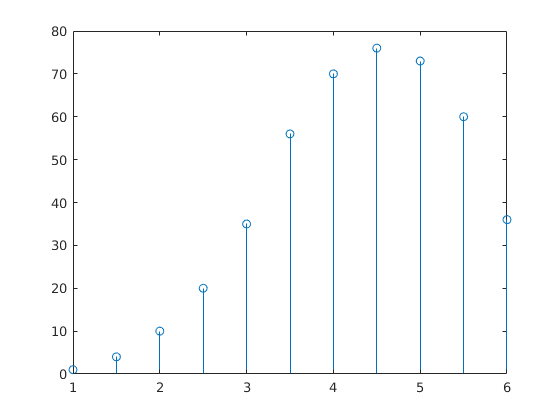

N = 2; % Running the summation of two X_i

C = conv(X,X);
d = size(C);
s = d(1,2);
X_new = linspace(1,6,s);
stem(X_new,C)

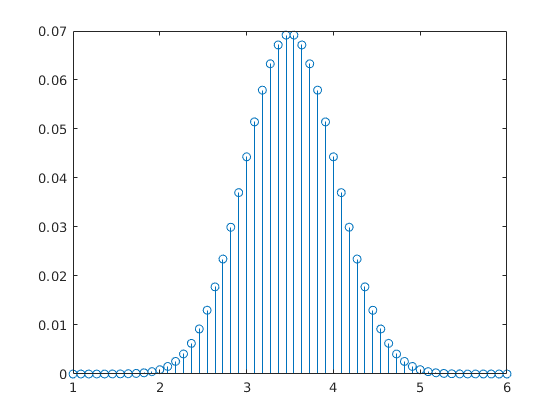

N = 10; % Running the summation of ten X_i

for i = 1:N
    if i==1
        C = conv(Y,Y);
    else
        C = conv(C,Y);
    end    
end

d = size(C);
s = d(1,2);
X_new = linspace(1,6,s);

stem(X_new,C)

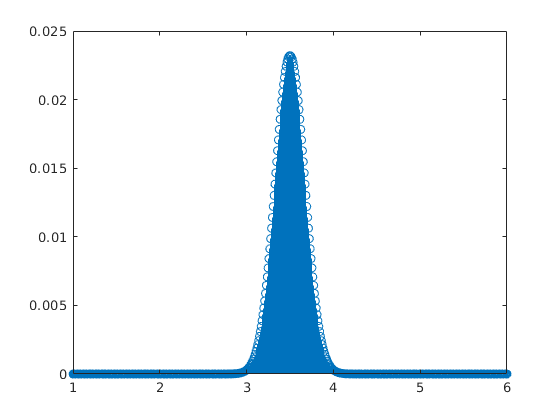

N = 100; % Running the summation of  X_i

for i = 1:N
    if i==1
        C = conv(Y,Y);
    else
        C = conv(C,Y);
    end    
end

d = size(C);
s = d(1,2);
X_new = linspace(1,6,s);

stem(X_new,C)